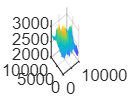

clc;
clear;
z = load('C:\Users\shubh\OneDrive - Clemson University\CUICAR\fall_2022\Me-optimal_control\ME822_project\elevation_data\map.txt');

xv = [0:50:50*(size(z,2)-1)];
x = xv;
for i=1:size(z,2)-1
    x = [x; xv];
end

yv = [0:50:50*(size(z,1)-1)]';
y = yv;
for i=1:size(z,1)-1
    y= [y, yv];
end

clear xv yv;

figure(1);
surf(x, y, z);
shading interp;

%saving to .mat
elev.x = x(1:10,1:10);
elev.y = y(1:10,1:10);
elev.z = z(1:10,1:10);
save('elevation_data_mini.mat', 'elev');